********************
* SensorDataReader started on 192.168.31.5:3400
********************
Connection accepted from 192.168.31.116:41376


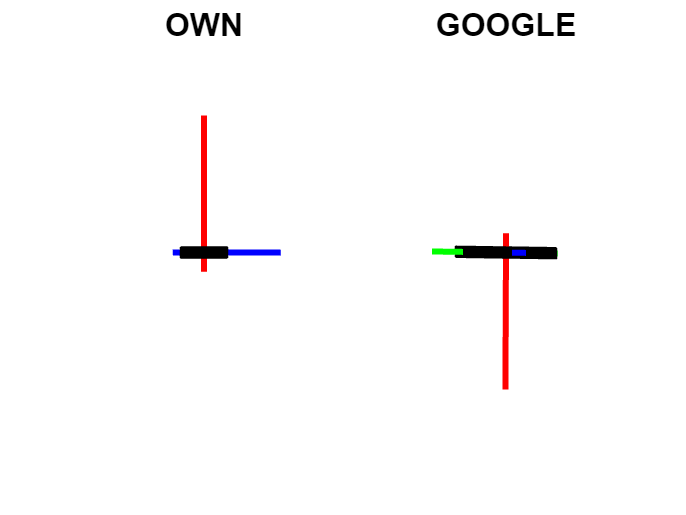

[xhat, meas] = filterTemplate();

# Task2

%filter and away from disturbance

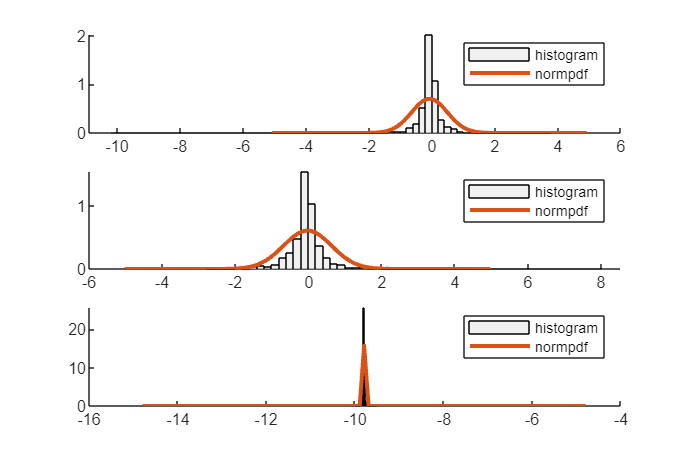

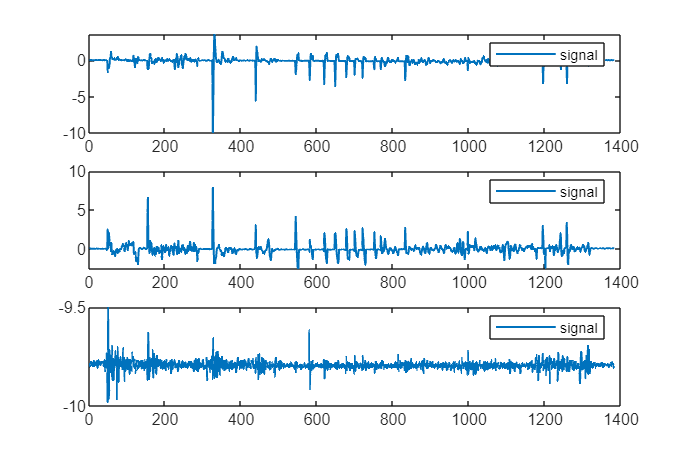

[mu_acc, Sigma_acc] = approxGaussianTransform(meas.acc(:, ~any(isnan(meas.acc), 1)));
[mu_gyr, Sigma_gyr] = approxGaussianTransform(meas.gyr(:, ~any(isnan(meas.gyr), 1)));
[mu_mag, Sigma_mag] = approxGaussianTransform(meas.mag(:, ~any(isnan(meas.mag), 1)));
t1=meas.acc(:, ~any(isnan(meas.acc),1));
t2=meas.acc(:, ~any(isnan(meas.gyr),1));
t3=meas.acc(:, ~any(isnan(meas.mag),1));
plothistogram(meas.acc,mu_acc,Sigma_acc,5,t1);

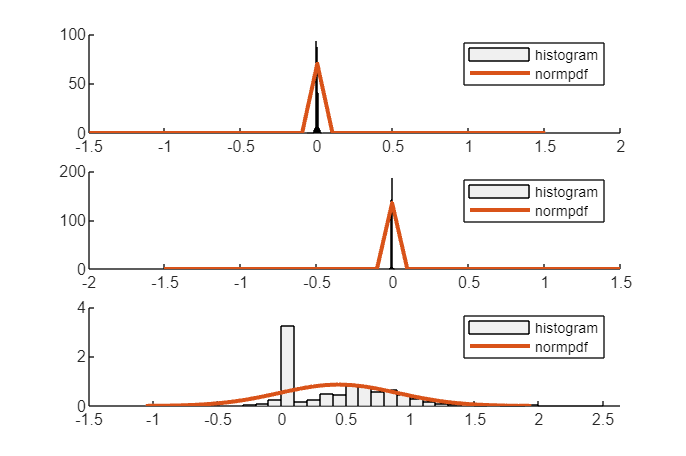

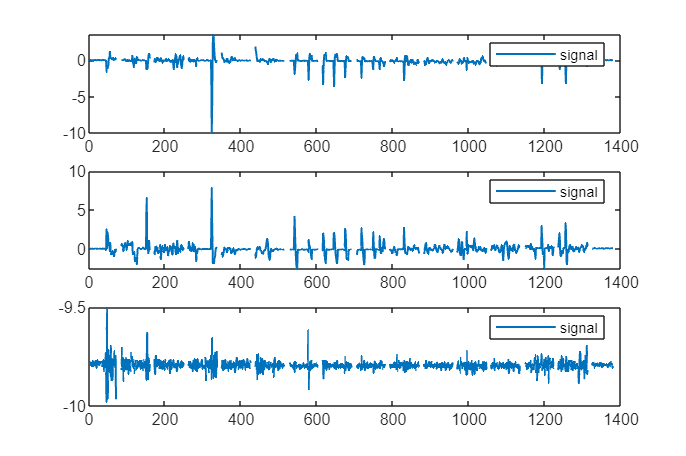

plothistogram(meas.gyr,mu_gyr,Sigma_gyr,1.5,t2);

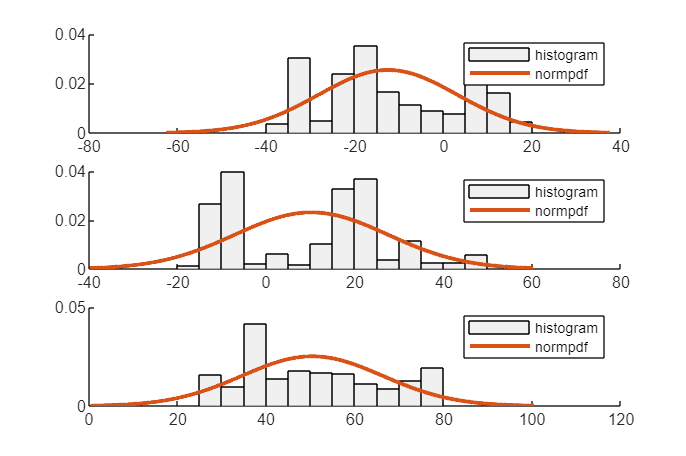

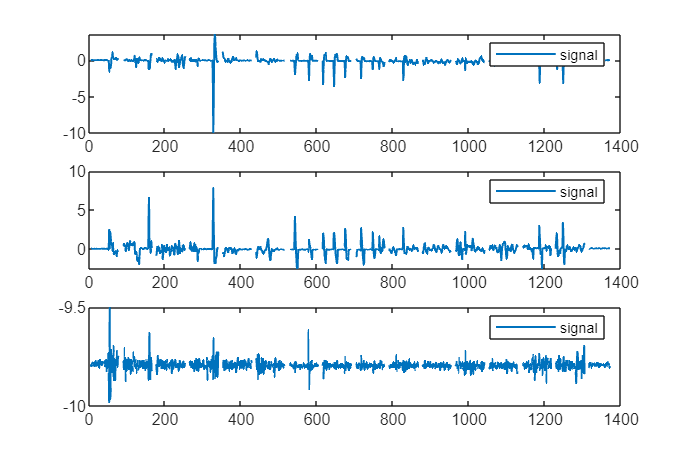

plothistogram(meas.mag,mu_mag,Sigma_mag,50,t3);

# Task 3

%see note

# Task 4